# Pruebas de código

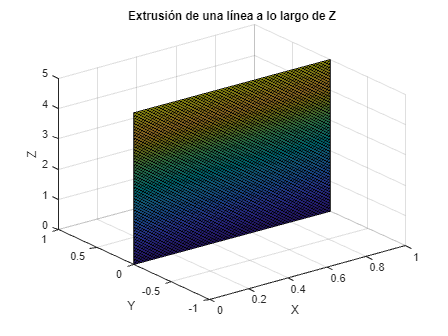

% Definimos la línea inicial en el plano XY
x = [0, 1];
y = [0, 0];
z = [0, 0];

% Definimos la trayectoria de extrusión (en este caso, una simple línea recta)
extrude_length = 5; % longitud de extrusión
num_points = 100; % número de puntos en la trayectoria

% Generamos la trayectoria en Z
z_trayectoria = linspace(0, extrude_length, num_points);

% Replicamos los puntos iniciales a lo largo de la trayectoria
X = repmat(x, num_points, 1);
Y = repmat(y, num_points, 1);
Z = repmat(z_trayectoria', 1, length(x));

% Graficamos la superficie extruida
surf(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Extrusión de una línea a lo largo de Z');

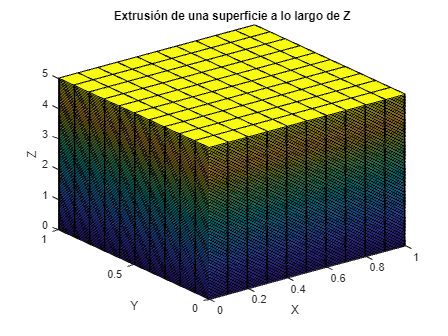

% Definimos la superficie inicial en el plano XY
[X, Y] = meshgrid(0:0.1:1, 0:0.1:1);
Z = zeros(size(X));

% Definimos la trayectoria de extrusión (en este caso, una línea recta en Z)
extrude_length = 5; % longitud de extrusión
num_points = 100; % número de puntos en la trayectoria

% Generamos la trayectoria en Z
z_trayectoria = linspace(0, extrude_length, num_points);

% Inicializamos matrices para almacenar el volumen extruido
volume_X = repmat(X, [1, 1, num_points]);
volume_Y = repmat(Y, [1, 1, num_points]);
volume_Z = repmat(reshape(z_trayectoria, [1, 1, num_points]), size(X, 1), size(X, 2));

% Graficamos el volumen extruido
figure;
for i = 1:num_points
    surf(volume_X(:,:,i), volume_Y(:,:,i), volume_Z(:,:,i));
    hold on;
end
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Extrusión de una superficie a lo largo de Z');

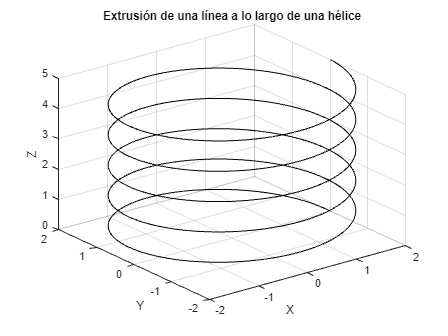

% Definimos la línea inicial en el plano XY
x = [0, 0];
y = [0, 0];
z = [0, 1];

% Definimos los parámetros de la hélice
radius = 2; % radio de la hélice
height = 5; % altura total de la hélice
num_turns = 5; % número de vueltas de la hélice
num_points = 500; % número de puntos a lo largo de la hélice

% Generamos la trayectoria helicoidal
theta = linspace(0, 2*pi*num_turns, num_points);
x_trayectoria = radius * cos(theta);
y_trayectoria = radius * sin(theta);
z_trayectoria = linspace(0, height, num_points);

% Replicamos los puntos iniciales a lo largo de la trayectoria helicoidal
X = repmat(x, num_points, 1) + repmat(x_trayectoria', 1, length(x));
Y = repmat(y, num_points, 1) + repmat(y_trayectoria', 1, length(x));
Z = repmat(z_trayectoria', 1, length(x));

% Graficamos la superficie extruida a lo largo de la hélice
figure;
surf(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Extrusión de una línea a lo largo de una hélice');

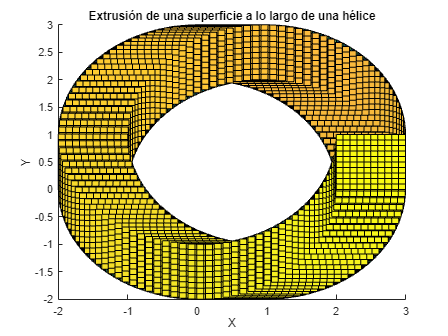

% Definimos la superficie inicial en el plano XY
[X, Y] = meshgrid(0:0.1:1, 0:0.1:1);
Z = zeros(size(X));

% Definimos los parámetros de la hélice
radius = 2; % radio de la hélice
height = 5; % altura total de la hélice
num_turns = 5; % número de vueltas de la hélice
num_points = 500; % número de puntos a lo largo de la hélice

% Generamos la trayectoria helicoidal
theta = linspace(0, 2*pi*num_turns, num_points);
x_trayectoria = radius * cos(theta);
y_trayectoria = radius * sin(theta);
z_trayectoria = linspace(0, height, num_points);

% Inicializamos matrices para almacenar el volumen extruido
volume_X = repmat(X, [1, 1, num_points]) + reshape(x_trayectoria, [1, 1, num_points]);
volume_Y = repmat(Y, [1, 1, num_points]) + reshape(y_trayectoria, [1, 1, num_points]);
volume_Z = repmat(Z, [1, 1, num_points]) + reshape(z_trayectoria, [1, 1, num_points]);

% Graficamos el volumen extruido a lo largo de la hélice
figure;
hold on;
for i = 1:num_points
    surf(volume_X(:,:,i), volume_Y(:,:,i), volume_Z(:,:,i));
end
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Extrusión de una superficie a lo largo de una hélice');
hold off;

# Graficador codigo G

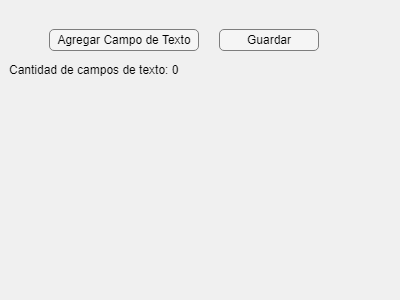

function createGUI(variableName)
    % Crear la figura de la interfaz gráfica
    fig = uifigure('Position', [100, 100, 400, 300], 'Name', 'Inserción de Campo de Texto');
    
    % Crear un botón para agregar un campo de texto
    btnAdd = uibutton(fig, 'push', 'Text', 'Agregar Campo de Texto', ...
        'Position', [50, 250, 150, 22], ...
        'ButtonPushedFcn', @(btn,event) addTextArea(fig));

    % Crear un botón para guardar el contenido del campo de texto
    btnSave = uibutton(fig, 'push', 'Text', 'Guardar', ...
        'Position', [220, 250, 100, 22], ...
        'ButtonPushedFcn', @(btn,event) saveTextAreaContent(fig, variableName));
    
    % Crear una etiqueta para mostrar la cantidad de campos de texto
    lbl = uilabel(fig, 'Text', 'Cantidad de campos de texto: 0', ...
        'Position', [10, 220, 200, 22], ...
        'Tag', 'CountLabel');
end

function addTextArea(fig)
    % Contar la cantidad actual de campos de texto
    currentTextAreas = findall(fig, 'Type', 'uitextarea');
    count = length(currentTextAreas);

    % Actualizar la posición para el nuevo campo de texto
    newPosition = [10, 200 - 30*count, 380, 22];

    % Crear un nuevo campo de texto
    uitextarea(fig, 'Position', newPosition, 'Tag', ['TextArea', num2str(count + 1)]);

    % Actualizar la etiqueta con la nueva cantidad de campos de texto
    lbl = findall(fig, 'Tag', 'CountLabel');
    lbl.Text = ['Cantidad de campos de texto: ', num2str(count + 1)];
end

function saveTextAreaContent(fig, variableName)
    % Obtener todos los campos de texto
    textAreas = findall(fig, 'Type', 'uitextarea');
    
    % Inicializar una celda para almacenar los contenidos
    contents = cell(length(textAreas), 1);
    
    % Recorrer todos los campos de texto y guardar sus contenidos
    for i = 1:length(textAreas)
        contents{i} = textAreas(i).Value;
    end
    
    % Asignar los contenidos a la variable en el espacio de trabajo base
    assignin('base', variableName, contents);
    
    % Mensaje de confirmación
    uialert(fig, 'Contenido guardado correctamente', 'Confirmación');
end

% Ejemplo de uso:
createGUI('miCampoDeTexto');

tabla_trayectorias = = table(X, Y, A, F);
var_tray = ()


